close all;
clear;

src = cd;
dataDir = fullfile(src, "\daffodilSeg");
imDir = fullfile(dataDir,'ImagesRsz256');
pxDir = fullfile(dataDir,'LabelsRsz256');


imds = imageDatastore(imDir);

classNames = ["flower" "leaf" "background" "sky"];

pixelLabelID = [1 2 3 4];

%groundtruth labels
pxds = pixelLabelDatastore(pxDir,classNames,pixelLabelID);
if ~exist(dataDir + "\temp", 'dir')
    mkdir(dataDir + "\temp")
end

for i = 1:size(pxds.Files, 1)
l = pxds.read();
l = l{1};
binL = l == 'flower';
% Convert the categorical array to a matrix of integer values
labelMatrix = uint8(binL);

% Save the label matrix as an image
index = sprintf('%04d', i);
imwrite(labelMatrix, dataDir + "\temp\groundtruth" + index + ".png");
end

classNames = ["background" "flower"];

pxds =  pixelLabelDatastore(fullfile(dataDir + "\temp"),classNames ,[0 1]);

[imdsTrain, imdsVal, pxdsTrain, pxdsVal] = partitionCamVidData(imds,pxds);

trainLabels = transform(pxdsTrain, @catLabelsCell, 'IncludeInfo', true);
valLabels = transform(pxdsVal, @catLabelsCell, 'IncludeInfo', true);

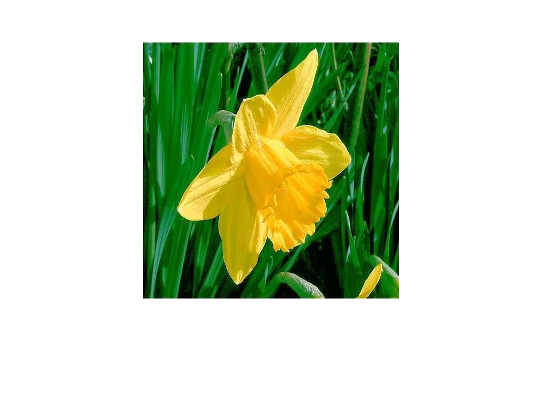

%show first input image
I = readimage(imdsTrain,1);
figure
imshow(I)


C = read(trainLabels);
C = C{1};

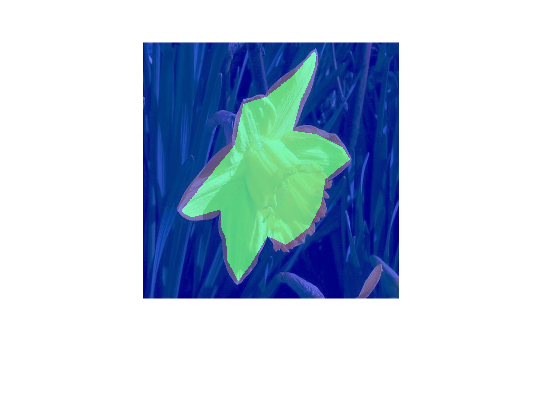

%show overlaid groundtruth labels as an example
B = labeloverlay(I,C); %overlay
figure;
imshow(B);

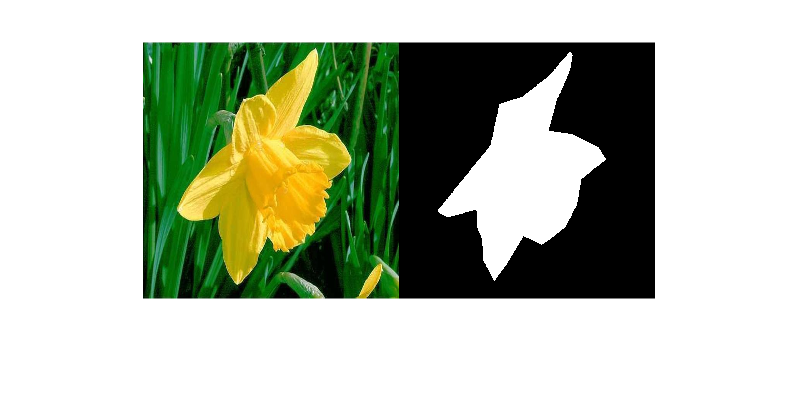

%example binary seg
flowerMask = C == 'flower';
figure
imshowpair(I, flowerMask,'montage')

trainingData = combine(imdsTrain,trainLabels);
validationData = combine(imdsVal,valLabels);

% DOWNSAMPLE
filterSize = 3;
numFilters = 64; 

poolSize = 2;

downsamplingBlock = [
    convolution2dLayer(filterSize,numFilters,'Padding',1)
    reluLayer()
    maxPooling2dLayer(poolSize,'Stride',2)
    ]

downsamplingBlock =   3×1 Layer array with layers:

     1   ''   2-D Convolution   64 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     2   ''   ReLU              ReLU
     3   ''   2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]


% UPSAMPLE

filterSize = 4;

upsamplingBlock = [
    transposedConv2dLayer(filterSize,numFilters,'Stride',2,'Cropping',1)
    reluLayer()
    ]

upsamplingBlock =   2×1 Layer array with layers:

     1   ''   2-D Transposed Convolution   64 4×4 transposed convolutions with stride [2  2] and cropping [1  1  1  1]
     2   ''   ReLU                         ReLU


% OUTPUT
numClasses = 2;
classWeights = [1 2];

finalLayers = [
    convolution2dLayer(1,numClasses)
    softmaxLayer()
    pixelClassificationLayer('Classes', {'background', 'flower'}, ...
    'ClassWeights', classWeights);
    ]

finalLayers =   3×1 Layer array with layers:

     1   ''   2-D Convolution              2 1×1 convolutions with stride [1  1] and padding [0  0  0  0]
     2   ''   Softmax                      softmax
     3   ''   Pixel Classification Layer   Class weighted cross-entropy loss with classes 'background' and 'flower'


% STACK

net = [
    imageInputLayer([256 256 3])    
    downsamplingBlock
    downsamplingBlock
    upsamplingBlock
    upsamplingBlock
    finalLayers
    ]

net =   14×1 Layer array with layers:

     1   ''   Image Input                  256×256×3 images with 'zerocenter' normalization
     2   ''   2-D Convolution              64 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   ''   ReLU                         ReLU
     4   ''   2-D Max Pooling              2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   2-D Convolution              64 3×3 convolutions with stride [1  1] and padding [1  1  1  1]
     6   ''   ReLU                         ReLU
     7   ''   2-D Max Pooling              2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   2-D Transposed Convolution   64 4×4 transposed convolutions with stride [2  2] and cropping [1  1  1  1]
     9   ''   ReLU                         ReLU
    10   ''   2-D Transposed Convolution   64 4×4 transposed convolutions with stride [2  2] and cropping [1 


opts = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-3, ...
    'MaxEpochs',25, ... 
    'ValidationData',validationData, ...
    'ValidationFrequency',5, ...
    'MiniBatchSize',64, ...
    'Verbose',false, ...
    'Plots','training-progress',...
    'ExecutionEnvironment','multi-gpu');

net = trainNetwork(trainingData,net,opts);

save('segnet.mat', 'net')

% load('segnet4.mat', 'net')
% deepNetworkDesigner(net);

pxdsResults = semanticseg(imdsVal,net);

Running semantic segmentation network
-------------------------------------
* Processed 14 images.



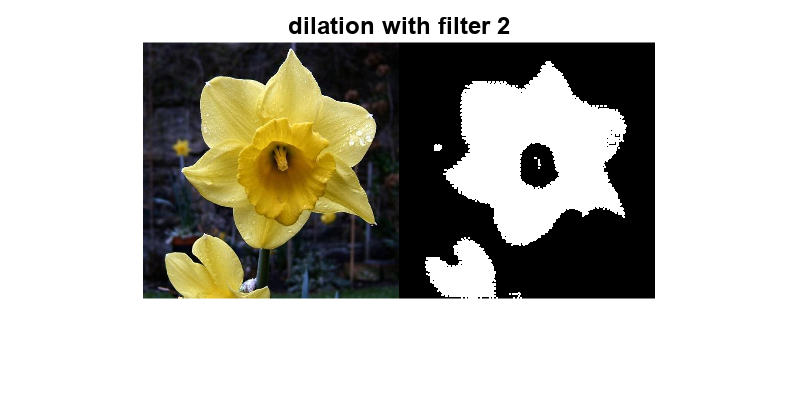

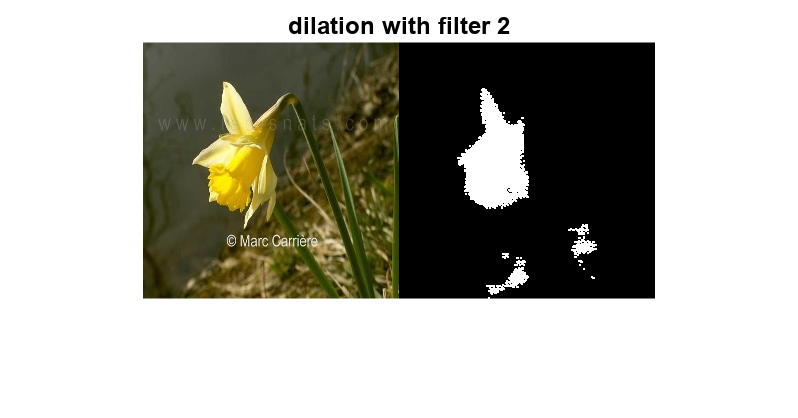

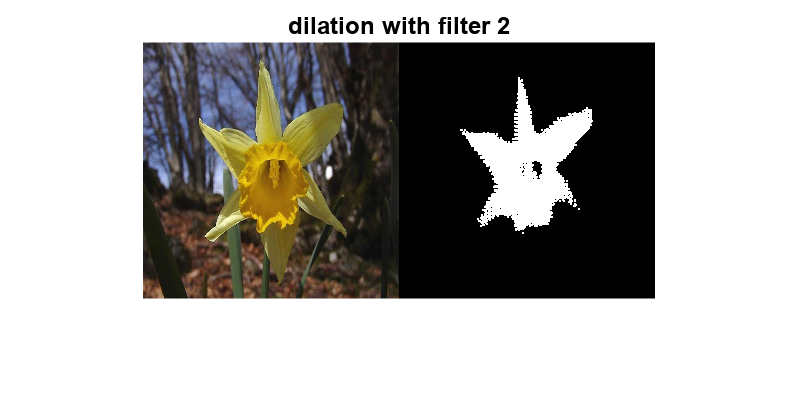

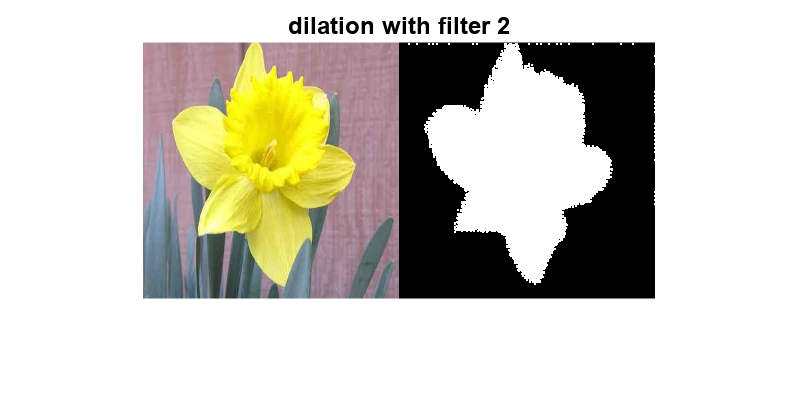

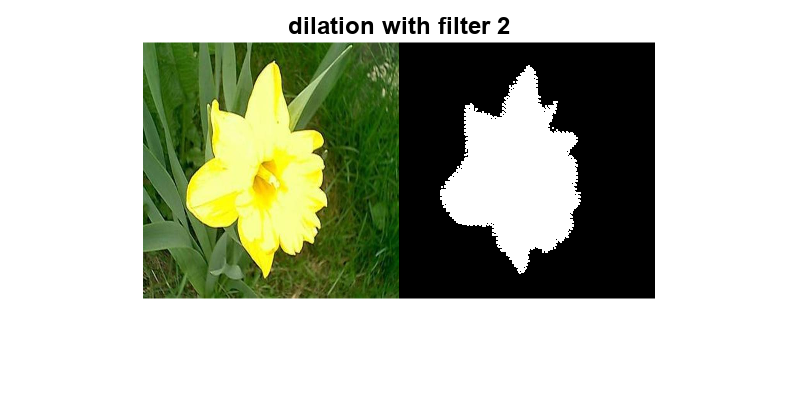

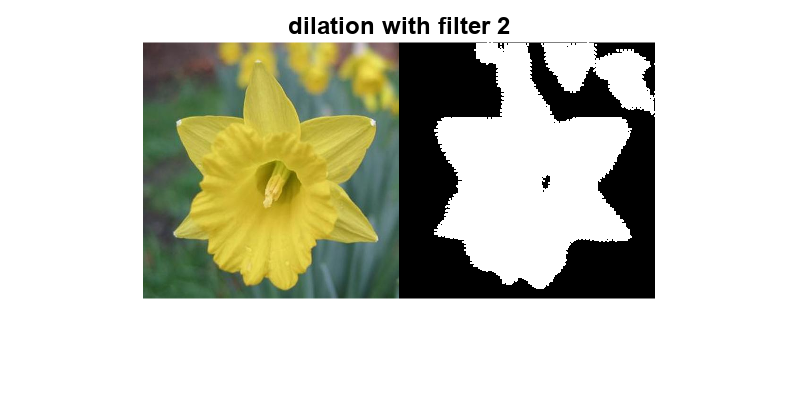

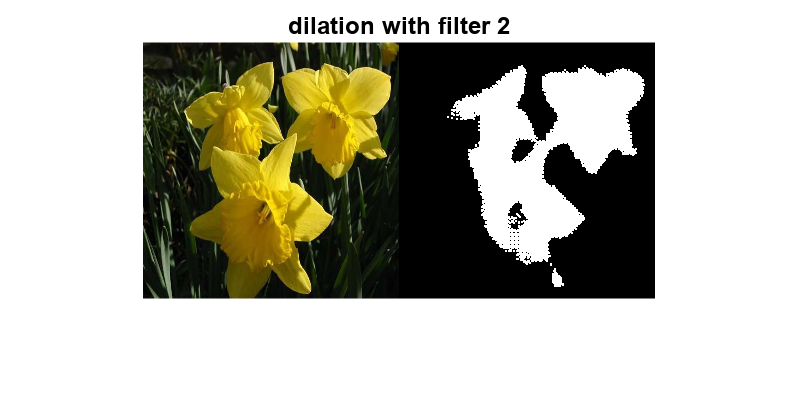

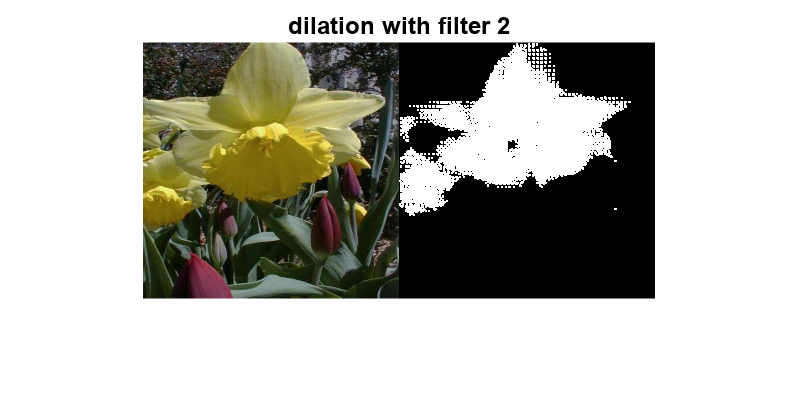

pxdsResults = diluteImages(imdsVal,pxdsResults,2);

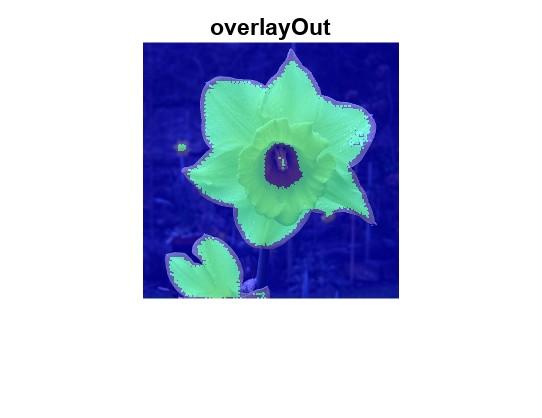

%show a couple of output images, overlaid
overlayOut = labeloverlay(readimage(imdsVal,1),readimage(pxdsResults,1)); %overlay
figure
imshow(overlayOut);
title('overlayOut')

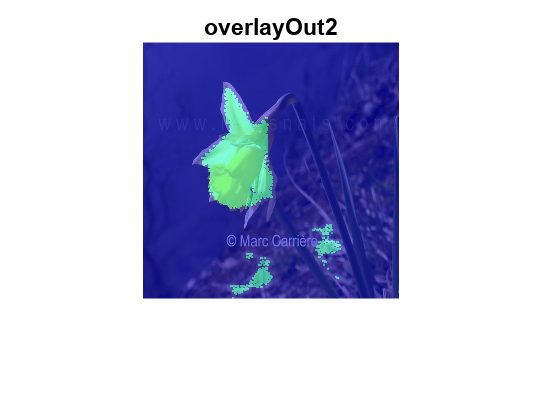


overlayOut = labeloverlay(readimage(imdsVal,2),readimage(pxdsResults,2)); %overlay
figure
imshow(overlayOut);
title('overlayOut2')

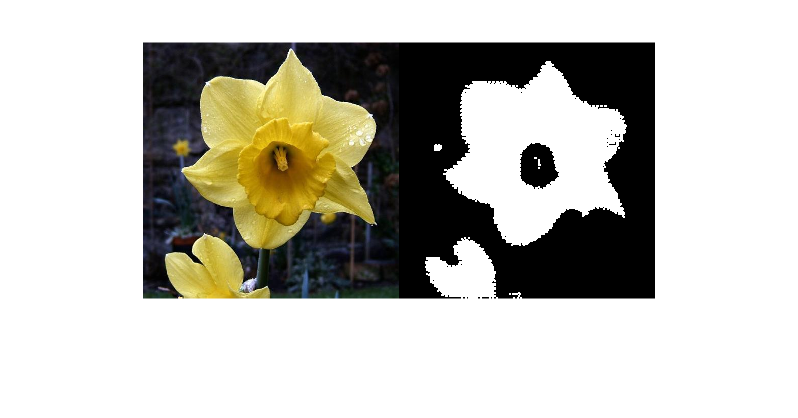


C = read(pxdsResults);
C = C{1};
I = readimage(imdsVal,1);
flowerMask = C == {'flower'};
figure;
imshowpair(I, flowerMask,'montage')

metrics = evaluateSemanticSegmentation(pxdsResults,valLabels)

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 14 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.93563          0.92165       0.85058      0.88135        0.61281  



metrics =   semanticSegmentationMetrics with properties:

              ConfusionMatrix: [2×2 table]
    NormalizedConfusionMatrix: [2×2 table]
               DataSetMetrics: [1×5 table]
                 ClassMetrics: [2×3 table]
                 ImageMetrics: [14×5 table]


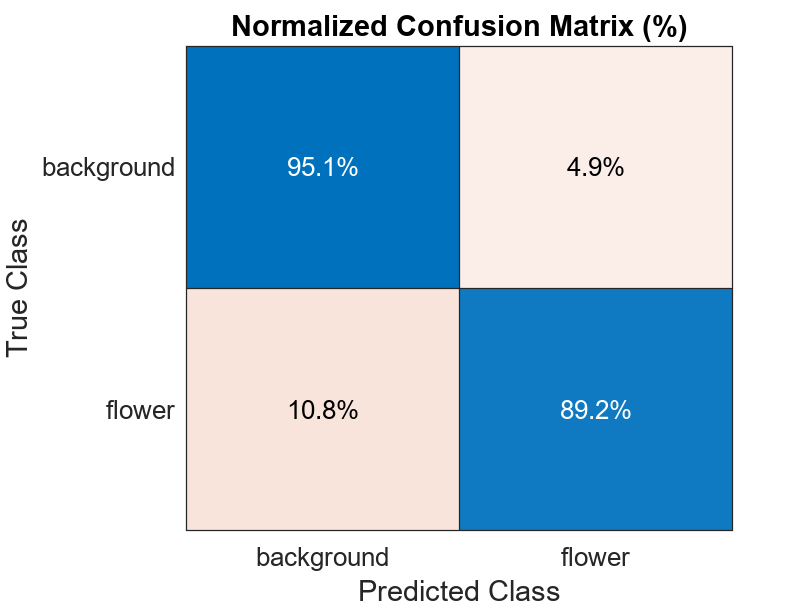

figure
cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
  classNames, Normalization='row-normalized');
cm.Title = 'Normalized Confusion Matrix (%)';

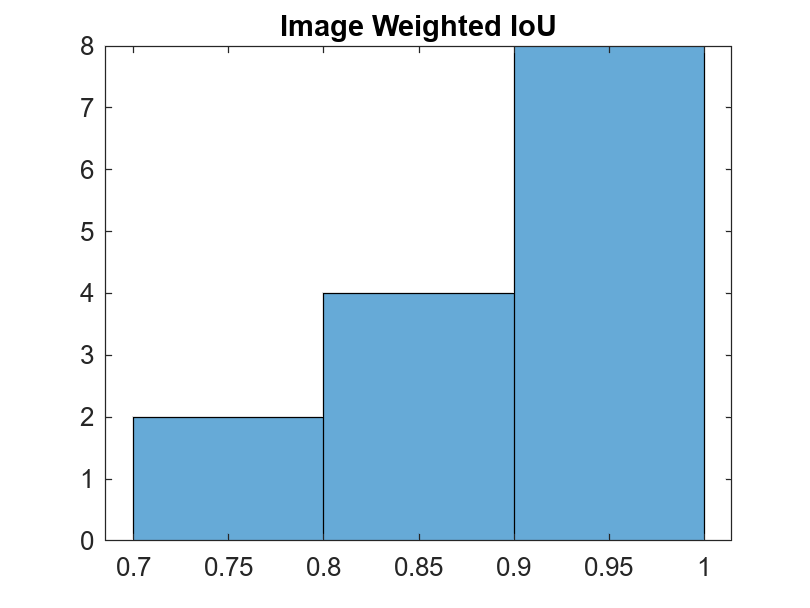


imageIoU = metrics.ImageMetrics.WeightedIoU;
figure
histogram(imageIoU)
title('Image Weighted IoU')

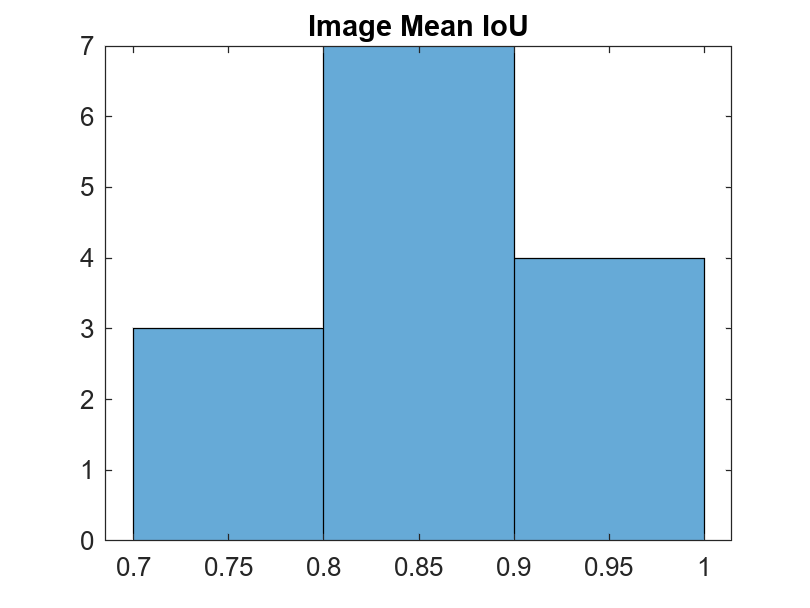


imageIoU = metrics.ImageMetrics.MeanIoU;
figure
histogram(imageIoU)
title('Image Mean IoU')


precision = mean(diag(metrics.ConfusionMatrix.Variables) ./ sum(metrics.ConfusionMatrix.Variables,2));
recall = mean(diag(metrics.ConfusionMatrix.Variables) ./ sum(metrics.ConfusionMatrix.Variables,1)');
F1score = 2 * (precision * recall) / (precision + recall);

precision

precision = 0.9216

recall

recall = 0.9144

F1score

F1score = 0.9180

function [outLabels, info] = catLabelsCell(inLabels, info)
    data = inLabels{1};
    outLabels = data;
    categories = categorical(["flower" "background"]);
    for i = 1:size(data,1)
        for j = 1:size(data,2)
            cellVal = data(i,j);
            switch cellVal
                case "flower"
                    temp = categories(1);
                otherwise
                    temp = categories(2);
            end
            outLabels(i,j) = temp;
        end
    end
    outLabels = {outLabels};
end

function [imdsTrain, imdsVal, pxdsTrain, pxdsVal] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);
% Use 80% of the images for training.
numTrain = round(0.80 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);
% Use 10% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);
% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = [0 1];
% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
end

function dilutedLabels = diluteImages(imds, results, filterSize)
results.reset()
imds.reset()
for i = 1:size(results.Files,1)
    figure;
    se = strel("square", filterSize);
    
    labels= results.read();
    labels = labels{1};
    binImg = labels == 'flower';
    
    errodedC = imerode(binImg, se);
    dilatedC = imdilate(errodedC, se);

    img = imds.read();
    imshowpair(img, dilatedC,'montage')
    title("dilation with filter " + filterSize)
    
    binaryMatrix = uint8(dilatedC);
    
    % Save the binary matrix as an image
    index = sprintf('%04d', i);
    imwrite(binaryMatrix, dataDir + "\Output\pixelLabel_" + index + ".png");
end
dilutedLabels = pixelLabelDatastore(fullfile(dataDir + "\Output"), ...
    ["background" "flower"], [0 1]);
end